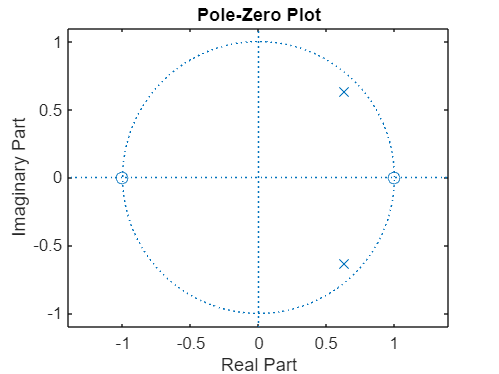

a = 0.9; 
w0 = pi/4;
b0 = (1 - a^2) / 2; % Such that H(z) tends to 1

% Transfer function
num = b0 * [1 0 -1]; 
den = [1 -2*a*cos(w0) a^2];

% Pole-zero plot
figure;
zplane(num, den);
title('Pole-Zero Plot');

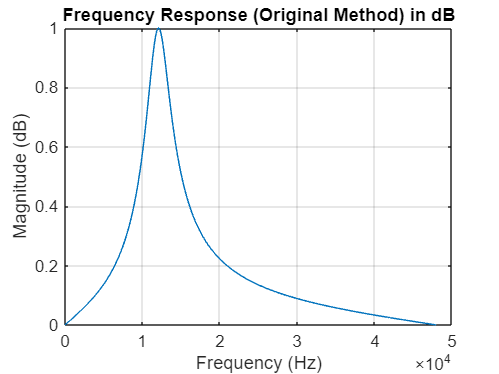


% Frequency response
[H_1, f] = freqz(num, den, 1000, 96000);
figure;
plot(f, (abs(H_1)));
title('Frequency Response (Original Method) in dB');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;